# Búið til Qin gögn

clear all; close all; clc;

% Oft þarf að loka .xlsx skránni áður en þessi Matlab kóði er keyrður
% TableName = 'Qin_new_5Days_Flod';
% TableName = 'Qin_new_3months';
TableName = 'Qin_new_1Day';
FileType  = '.xlsx';
FileName = append(TableName,FileType);
% Qin_Array = getTable(FileName); % Lesið inn excel töflu og sett í array

T_selected = readtable(TableName,'Sheet','Sheet1','ReadVariableNames',true);

dates = T_selected.Date;

Qin_Array = readtable(TableName,'Sheet','Sheet1','ReadVariableNames',false);
Qin_Array = Qin_Array.Var4;

newTime = datetime(T_selected.Time, "ConvertFrom", "excel");
times = timeofday(newTime);

t = table(dates,times);
fullt = t.dates + t.times;
fullDateTime = datetime(fullt,'InputFormat','yyyy-MM-dd HH:mm:ss.S', 'Format', 'yyyy-MM-dd HH:mm:ss.SSS');
firstdate = fullDateTime(1)

firstdate = datetime
   2020-10-01 00:00:00.000



% minutes(1)
% milliseconds(1)

N = length(Qin_Array)

N = 24

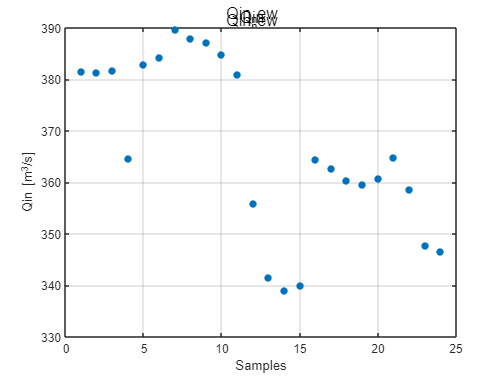


% Plots
figure;
sgtitle('Qin')
plot(Qin_Array,'*','LineWidth',2); 
ylabel('Qin [m^3/s]'); xlabel('Samples');
grid; 


Days = getDays(N);
time = 60*60*24*Days;

t0 = 0.0;
dt = 0.1;
samples = t0:dt:time-dt;
Nsim    = length(samples)        % Lengd sýnafylkis

Nsim = 864000


MS = milliseconds(dt*1000);
lastdate = fullDateTime(end) + minutes(59) + seconds(59) + milliseconds(999);
TT = firstdate:MS:lastdate;

% F = fillmissing(A,'constant',v)
% p_1 = polyfit(D,Cg,n);

% MS = milliseconds(dt*1000);
% 
% year  = 2020;
% month = 01;
% day   = 01;
% hour  = 00;
% min   = 00;
% sec   = 00;
% milli_sec = 000;
% 
% firstdate = datetime(year,month,day,hour,min,sec,milli_sec,'InputFormat','dd-MM-yyyy HH:mm:ss.SSS');
% firstdate.Format = 'uuuu/MM/dd HH:mm:ss.SSS'
% 
% lastdate = datetime(year,month,10,hour,min,sec,milli_sec-1,'InputFormat','dd-MM-yyyy HH:mm:ss.SSS');
% lastdate.Format = 'uuuu/MM/dd HH:mm:ss.SSS'
% XaxisScaled = firstdate:MS:lastdate;

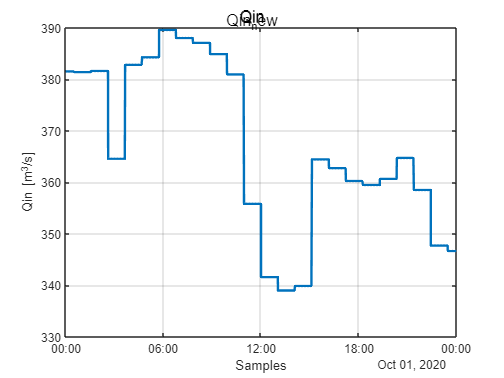

Qin_new(1:2,1:time) = 0;
Qin_new = interp1(1:N, Qin_Array, linspace(1, N, Nsim), 'nearest');
% time_1 = (0:(Days/(length(Qin_new)-1)):Days);

% Plots
figure;
sgtitle('Qin_new')
plot(TT,Qin_new,'LineWidth',2); 
ylabel('Qin [m^3/s]'); xlabel('Samples');
grid; 


% TF = isnan(Qin_new);
% any(TF, 'all') % Check if there is a NaN in the dataset

Qin_new(2,1) = Days;

dt2(1,1:Nsim) = dt;

TableOut = table(Qin_new(1,:)',TT',Qin_new(2,:)',dt2');
TableOut.Properties.VariableNames = ["Data","Time","Days","dt"];

% STR = append(TableName,'.mat')
% save(STR,'Qin_new');
TableOutName = append(TableName,'_saved');
TableOutName = append(TableOutName,'.txt');
writetable(TableOut,TableOutName);

% TT_TEST = readtable(TableOutName);

% TableTest = table(Qin_new(1,1:4)',TT(1:4)',Qin_new(2,1:4)');

% function table = getTable(TableName)
% 
%     %per_val = [0 4 8 12 16 20 24 28 32 36 40 44 48 52 56 60 64 68 72 76 80 84 88 92 96 100];
% 
%     %T_selected = readtable('Tables\4percentOpening_Table.xlsx','Sheet','Sheet1','Range','A2:D77');
%     T_selected = readtable(TableName,'Sheet','Sheet1','Range','D:D','ReadVariableNames',false);
% %     T_selected = readtable(TableName,'Sheet','Sheet1','ReadVariableNames',true);
% 
%     table = table2array(T_selected);
% 
%     clear T_selected
% end

function D = getDays(N)
    % Mikilvægt er að jafn mikill fjöldi sýna sé á hverjum degi

    SamplesPerDay = 24;

    count   = 0;
    i_count = 0;

    for i=1:N
        i_count = i_count + 1;
        if i_count == SamplesPerDay
            count = count + 1;
            i_count = 0;
        end
    end

    D = count;
end